# CCNY Ozone-DIAL retrievals

Orignially written by Dr.Li in 2022-2023-2024

Wu add: aerosol correction for the O3 retrievals at near-range channel Aug.28, 2024

clearvars; close all;

addpath(genpath('./functions'));

% download_path = './input_data/';
download_path = 'C:\Users\Thomas Ely\OneDrive - The City College of New York\Desktop\input_data\';
% download_path = 'C:\Users\tely1\OneDrive - The City College of New York\Desktop\input_data\';
% download_path = 'C:\Users\Thomas\OneDrive - The City College of New York\Desktop\input_data\';

download_data = false;
save_figs = false;

## Load lidar data files, get time average, dead-time correction, and background-noise subtraction 

file_date_dt = datetime("2023-09-20", "InputFormat", "uuuu-MM-dd"); file_date = string(datetime(file_date_dt, "Format","uuuuMMdd"));
folder_path = strcat(download_path, file_date, '/txt/');
save_path = strcat('./results/', file_date,'/');
[st,f] = mkdir(save_path);

nbin = 8000;
dzm = 3.75;
bgbins = 100;
td = 280;
nAvg = 10;
sib_hkm = 12; % the begining range for sib correction fitting curve

if download_data == true
    download_lidar_data(file_date_dt, download_path)
end

% for the first time run, load the orignial txt files into mat file
OLfileName = read_OL_profiles(folder_path, save_path, nbin, dzm, bgbins, td, nAvg, sib_hkm);
load(OLfileName);

ids = size(sigprof.an287fr, 2);

## Raw Signal Profiles Plot

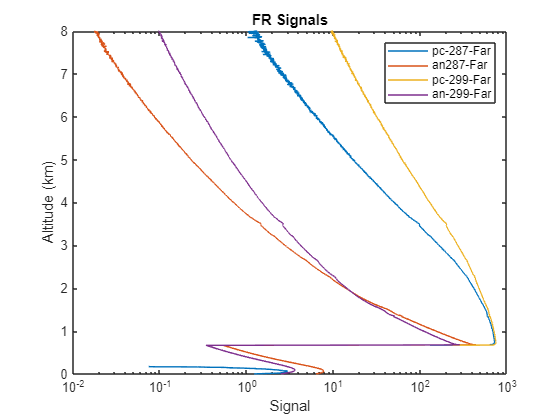

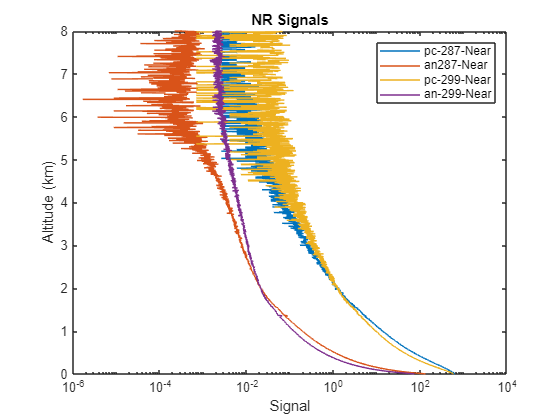

Show = true;
if Show == true
    id = 1;
    signal_plot('FR Signals',{'pc-287-Far','an287-Far','pc-299-Far','an-299-Far'},id,sigprof.pc287fr,sigprof.an287fr,sigprof.pc299fr,sigprof.an299fr, hkm)
    signal_plot('NR Signals',{'pc-287-Near','an287-Near','pc-299-Near','an-299-Near'},id,sigprof.pc287nr,sigprof.an287nr,sigprof.pc299nr,sigprof.an299nr, hkm)
end

% Far-ch and near-ch PMT gate start time
% start_bin_fr = 190; % 190-bin = 4.75 us, 712.5 m, normally
start_bin_fr = 135; % 135-bin = 3.375 us, 506.25 m on Nov.15
start_bin_nr = 20;

[new_sigprof, hkm_fr, hkm_nr] = gate_prof(sigprof, start_bin_fr, start_bin_nr, hkm);

## Signals After gate_prof Plot

Show = true;

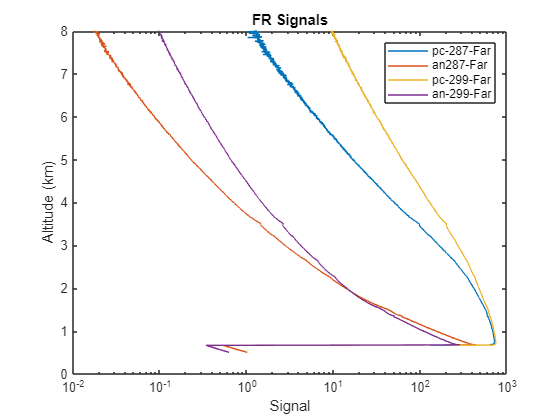

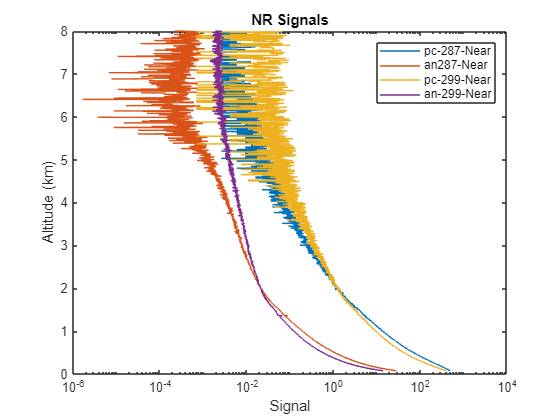

if Show == true
    id = 1;
    signal_plot('FR Signals',{'pc-287-Far','an287-Far','pc-299-Far','an-299-Far'},id,new_sigprof.pc287fr,new_sigprof.an287fr,new_sigprof.pc299fr,new_sigprof.an299fr,hkm_fr)
    signal_plot('NR Signals',{'pc-287-Near','an287-Near','pc-299-Near','an-299-Near'},id,new_sigprof.pc287nr,new_sigprof.an287nr,new_sigprof.pc299nr,new_sigprof.an299nr, hkm_nr)
end

## Cloud screening

 take derivative of the signal profile from the start bin the clouds are the place: 

- the signal at cloud base is larger than the signal below the cloud 

- negative derivative < Threshold

Merge far- and near range AD signal at 299 nm

start_merge_hkm = 0.83;

end_merge_hkm = 0.9;

% linear fitting coefficient calculating range
z1 = 0.8;
z2 = 1;

if all(isnan(sigprof.an287nr), "all") && all(isnan(sigprof.an299nr), "all") && all(isnan(sigprof.pc287nr), "all") && all(isnan(sigprof.pc299nr), "all")
    disp('skipping merge_nr_fr')
    prof_ad_287_fr_nr = sigprof.an287;
    prof_ad_299_fr_nr = sigprof.an299;
else
    prof_ad_299_fr_nr = merge_nr_fr_prof(new_sigprof.an299nr,new_sigprof.an299fr,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);
    prof_ad_287_fr_nr = merge_nr_fr_prof(new_sigprof.an287nr,new_sigprof.an287fr,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);
end

sgwin_len_cld = 31; % must be odd
cld_screen_prof_off = sgolayfilt(prof_ad_299_fr_nr,1,sgwin_len_cld);
cld_start_bin = 0.5; % 1km
cld_end_bin = 10; % 10km
dlen = 11;
Th_cld1 = 0.007; % threshold values, adjustable for dense smoke, clouds, etc.
Th_cld2 = 0.007;

grad_bg = -0.002;

cldNum = zeros(1,length(TimeInHour_avg));
cldBaseZ = nan(3,length(TimeInHour_avg));
cldTopZ = cldBaseZ;
cld_mask = false(size(cld_screen_prof_off));

**Need to make cloud screening work with older data without NR channel**

[cldNum, cldBaseZ, cldTopZ,cldBaseZ_ind, cldTopZ_ind, cldBase_qc_flag, cldTop_qc_flag, cld_mask, pz2, d_Pz2] = cld_detect2(cld_screen_prof_off, cld_start_bin, cld_end_bin, hkm_nr, Th_cld1, Th_cld2, dlen, grad_bg);

#### Cloud screen test

Show = false;
if Show == true
    plot_cld_screen_result(DateTime_avg, TimeInHour_avg, hkm_nr, movmean(pz2,5,1), movmean(d_Pz2,5,1), cldBaseZ, cldBaseZ_ind, cldTopZ, cldTopZ_ind)
end

#### PD/AD Signal Plot

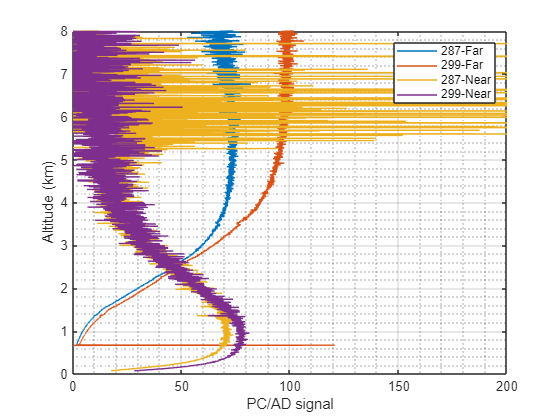

Show = true;
if Show == true
    id = 1;
    figure
    plot(new_sigprof.pc287fr(:,id)./new_sigprof.an287fr(:,id),hkm_fr); hold on
    plot(new_sigprof.pc299fr(:,id)./new_sigprof.an299fr(:,id),hkm_fr);
    plot(new_sigprof.pc287nr(:,id)./new_sigprof.an287nr(:,id),hkm_nr); hold on
    plot(new_sigprof.pc299nr(:,id)./new_sigprof.an299nr(:,id),hkm_nr);
    xlim([0,200]);legend('287-Far','299-Far','287-Near','299-Near')
    ylim([0,8]);grid on; grid minor;
    xlabel('PC/AD signal');
    ylabel('Altitude (km)');
end

Glue the ad and pc signals: be careful to the clouds

[new_sigprof.merge287fr, regR287] = adpc_glue_func_cldscr(new_sigprof.an287fr,new_sigprof.pc287fr,5.5,6.5,hkm_fr,cldNum,cldBaseZ, cldTopZ);
[new_sigprof.merge299fr, regR299] = adpc_glue_func_cldscr(new_sigprof.an299fr,new_sigprof.pc299fr,5.5,6.5,hkm_fr,cldNum,cldBaseZ, cldTopZ);
[new_sigprof.merge287frsib, regR287] = adpc_glue_func_cldscr(new_sigprof.an287frsib,new_sigprof.pc287frsib,5.5,6.5,hkm_fr,cldNum,cldBaseZ, cldTopZ);
[new_sigprof.merge287nr, regR287nr] = adpc_glue_func_cldscr(new_sigprof.an287nr,new_sigprof.pc287nr,1,1.1,hkm_nr,cldNum,cldBaseZ, cldTopZ);

[new_sigprof.merge299nr, regR299nr] = adpc_glue_func_cldscr(new_sigprof.an299nr,new_sigprof.pc299nr,1,1.1,hkm_nr,cldNum,cldBaseZ, cldTopZ);

Merge the far and near range signal

% Merge range
start_merge_hkm = 0.9;
end_merge_hkm = 1;

% linear fitting coefficient calculating range
z1 = 0.9;
z2 = 1;
new_sigprof.merge287merge = merge_nr_fr_prof(new_sigprof.merge287nr,new_sigprof.merge287frsib,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);
new_sigprof.merge287mergesib = merge_nr_fr_prof(new_sigprof.an287nr,new_sigprof.merge287frsib,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);
new_sigprof.merge299merge = merge_nr_fr_prof(new_sigprof.merge299nr,new_sigprof.merge299fr,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);

#### Cloud screened smoothed profiles

Show = true;

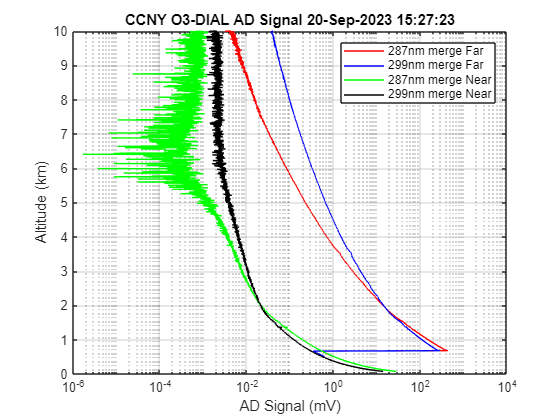

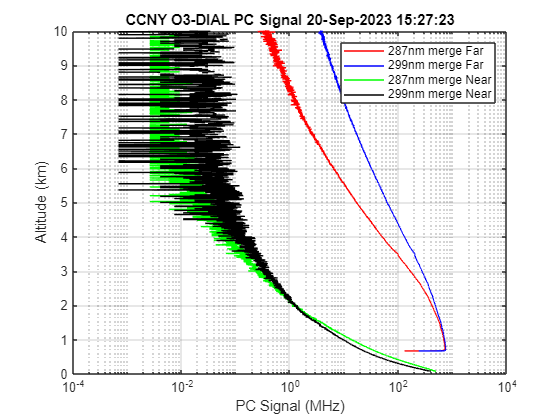

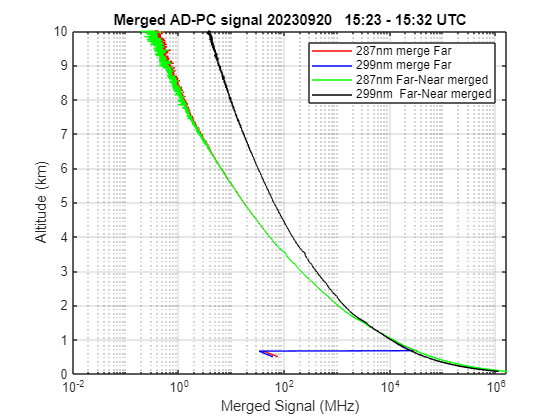

if Show == true
    id =1;

    y_lim = [0,10];
    tit_str='CCNY O3-DIAL AD Signal ';
    xlb='AD Signal (mV)';
    le={'287nm merge Far','299nm merge Far','287nm merge Near','299nm merge Near'};
    plot_fr_nr_Prof(new_sigprof.an287frsib,new_sigprof.an299fr,new_sigprof.an287nr,new_sigprof.an299nr,hkm_fr,hkm_nr,DateTime_avg,id,tit_str,xlb,y_lim,le);

    y_lim = [0,10];
    tit_str='CCNY O3-DIAL PC Signal ';
    xlb='PC Signal (MHz)';
    le={'287nm merge Far','299nm merge Far','287nm merge Near','299nm merge Near'};
    plot_fr_nr_Prof(new_sigprof.pc287fr,new_sigprof.pc299fr,new_sigprof.pc287nr,new_sigprof.pc299nr,hkm_fr,hkm_nr,DateTime_avg,id,tit_str,xlb,y_lim,le);

    xlb ='Merged Signal (MHz)';
    le = {'287nm merge Far','299nm merge Far','287nm Far-Near merged','299nm  Far-Near merged'};
    plot_fr_nr_Prof(new_sigprof.merge287fr,new_sigprof.merge299fr,new_sigprof.merge287merge,new_sigprof.merge299merge,hkm_fr,hkm_nr,DateTime_avg,id,tit_str,xlb,y_lim,le);
    title_str = strjoin(['Merged AD-PC signal',string(DateTime(1),'yyyyMMdd'),' ', string(DateTime((id-1)*nAvg+1),'HH:mm'),'-', string(DateTime(min([id*nAvg,length(TimeInHour)])),'HH:mm'),'UTC']);
    title(title_str)
end

## Calculate air density

- Option 1: using International Standard Atmosphere (ISA)

- Option 2: using micro-radiometer data (10-min resolution/daily average)

- Option 3: using radiosonde 

air_density_option = 3;

sigmaOn = 203.4*10^(-20); % O3 cross section at 287.2 (cm^2/molecule)
sigmaOff = 45.51*10^(-20); % O3 cross section at 299.1 (cm^2/molecule)
d_sigma = (sigmaOn-sigmaOff)*(10^-2)^2; % delta cross section (m^2/molecule)
load('./auxiliary_data/dsigma_287d1_299d2_temperature_lookup.mat');

% Option 1: Standard T and P profile,
if air_density_option == 1
    p0 = 1013.25*1e2; % surface pressure 1013.25 hpa = 101325pa
    T0 = 288.15; % surface temp (K)
    [NDAir_m3_prof,D_molex_prof, am287, am299] = isa_NDair_m3(hkm_nr,p0,T0,d_sigma);
    len_t = length(TimeInHour_avg);
    NDAir_m3 = repmat(NDAir_m3_prof, 1,len_t);
    D_molex = repmat(D_molex_prof, 1,len_t);

elseif air_density_option == 2

% Option 3: using radiosonde data
elseif air_density_option == 3
    sondefile = './auxiliary_data/20241031_OKX_z12.txt';
    delimiter = 'tab';
    [NDAir_m3_prof,D_molex_prof,am287,am299,dsigma_hkm,P_prof,T_prof] = sonde_NDair_m3_dsigma_t(sondefile,hkm_nr,dsigma,dsigma_temp,delimiter);
    len_t = length(TimeInHour_avg);
    NDAir_m3 = repmat(NDAir_m3_prof, 1,len_t);
    D_molex = repmat(D_molex_prof, 1,len_t);
end

## Calculating the ozone number density from the p_on and p_off

diff_nr_fr = length(hkm_nr) - length(hkm_fr) + 1;
NDAir_m3_fr = NDAir_m3(diff_nr_fr:end,:);

D_molex_fr = D_molex(diff_nr_fr:end,:);
dsigma_hkm_fr = dsigma_hkm(diff_nr_fr:end);

h0 = 0.2; h1 = 1.2;
len0 = 11; len1 = 121;
[frame_len_nr,vres_eff_nr] = framelen_vrtRes(hkm_nr,h0,h1,len0,len1,dzm);

h0 = 1.2; h1 = 10;
len0 = 11; len1 = 551;
[frame_len_fr,vres_eff_fr] = framelen_vrtRes(hkm_fr,h0,h1,len0,len1,dzm);

N_O3_nr = nan(size(new_sigprof.merge287nr));
pon = new_sigprof.an287nr(hkm_nr<3,:);
poff = new_sigprof.an299nr(hkm_nr<3,:);
[N_O3_nr(hkm_nr<3,:)] = retrieve_o3ND_framelen(pon,poff,dsigma_hkm(hkm_nr<3),frame_len_nr(hkm_nr<3));
N_O3_nr = N_O3_nr - D_molex;

N_O3_fr = nan(size(new_sigprof.merge287fr));
pon = new_sigprof.merge287frsib(hkm_fr<12,:);
poff = new_sigprof.merge299fr(hkm_fr<12,:);
[N_O3_fr(hkm_fr<12,:)] = retrieve_o3ND_framelen(pon,poff,dsigma_hkm_fr(hkm_fr<12),frame_len_fr(hkm_fr<12));
N_O3_fr = N_O3_fr - D_molex_fr;

% Merge the ozone retrievals from the far-ch and near-ch (N_O3_merge)
start_merge_hkm = 0.83;
end_merge_hkm = 0.9;
N_O3_merge = merge_nr_fr_o3ND(N_O3_nr,N_O3_fr,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr);

k1 = find(hkm_nr>=start_merge_hkm,1,'first');
k2 = find(hkm_fr>=start_merge_hkm,1,'first');
vres_eff_mrg = vres_eff_nr;
vres_eff_mrg(k1:end) = vres_eff_fr(k2:end);

#### Effective Vertical Resolution Plot

Show = false;
if Show == true
    figure
    plot(vres_eff_mrg,hkm_nr,'-','LineWidth',1);
    xlabel('Effective Vertical Resolution (km)');
    ylabel('Altitude (km)');
    ylim([0,12]);
    grid on; legend('Merge')
    set(gca,'FontSize',15);
end

#### O3 Number Density Profile Plot

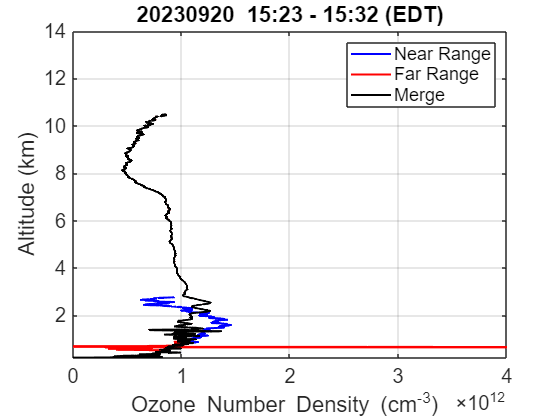

Show = true;
if Show == true
    le = {string(DateTime_avg(1), 'HH:mm'), string(DateTime_avg(2), 'HH:mm')};
    xlb ='Ozone Number Density (cm^{-3}) ';
    y_lim = [0.2,14];x_lim =[0,4e12];
    
    for k = 1
        figure
        plot(N_O3_nr(hkm_nr < 3.5,k) * 1e-6,hkm_nr(hkm_nr < 3.5), 'b-', 'LineWidth', 1.5); hold on;
        plot(N_O3_fr(:,k)*1e-6,hkm_fr,'r-','LineWidth',1.5);
        plot(N_O3_merge(:,k)*1e-6,hkm_nr,'k-','LineWidth',1.5);
        legend('Near Range','Far Range','Merge')
        xlabel(xlb);
        ylabel('Altitude (km)');
        title(strjoin([string(DateTime_avg(1),'yyyyMMdd '), string(DateTime((k-1)*nAvg+1),'HH:mm'),'-', string(DateTime(min([k*nAvg,length(TimeInHour)])),'HH:mm'),'(EDT)']))
        ylim(y_lim);xlim(x_lim);
        grid on
        set(gca,'FontSize',15)
    end
end

## Calculate the SNR

bg299_fr = repmat(sigprof.bgpc299,length(hkm_fr),1);
bg287_fr = repmat(sigprof.bgpc287,length(hkm_fr),1);
snr_299_fr = sqrt(nAvg*1200/40*(new_sigprof.merge299fr).^2./(new_sigprof.merge299fr+bg299_fr));
snr_287_fr = sqrt(nAvg*1200/40*(new_sigprof.merge287fr).^2./(new_sigprof.merge287fr+bg287_fr));

bg299_nr = repmat(sigprof.bgpc299nr,length(hkm_nr),1);
bg287_nr = repmat(sigprof.bgpc287nr,length(hkm_nr),1);
snr_299_nr = sqrt(nAvg*1200/40*(new_sigprof.merge299nr).^2./(new_sigprof.merge299nr+bg299_nr));
snr_287_nr = sqrt(nAvg*1200/40*(new_sigprof.merge287nr).^2./(new_sigprof.merge287nr+bg287_nr));

#### SNR Plot

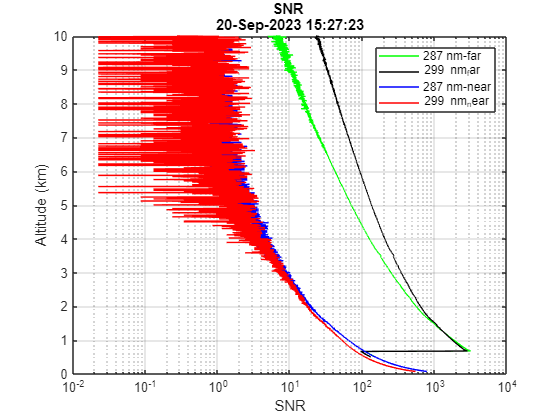

Show = true;
if Show == true
    id = 1;
    figure
    plot(snr_287_fr(:,id),hkm_fr,'g');hold on
    plot(snr_299_fr(:,id),hkm_fr,'k');
    plot(snr_287_nr(:,id),hkm_nr,'b');
    plot(snr_299_nr(:,id),hkm_nr,'r');
    set(gca,'XScale','log')
    legend('287 nm-far','299 nm_far','287 nm-near','299 nm_near')
    xlabel('SNR');
    ylabel('Altitude (km)');
    title(['SNR ',string(DateTime_avg(id))])
    ylim([0,10])
    grid on
end

## Calculate the O3 ppb

O3ppb_mrg = N_O3_merge./NDAir_m3*1e9;
O3ppb_fr = N_O3_fr./NDAir_m3_fr*1e9;
O3ppb_nr = N_O3_nr./NDAir_m3*1e9;

#### O3 Profile Plot

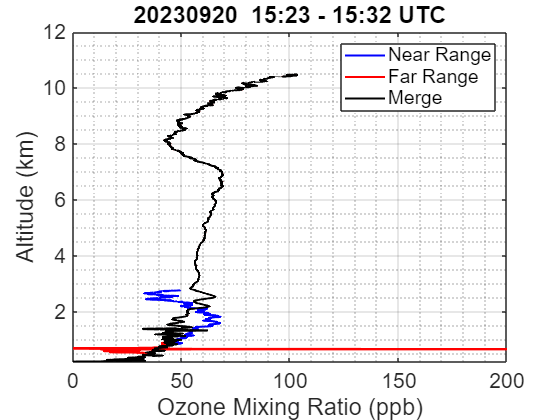

Show = true;
if Show == true
    id = 1;
    figure
    plot(O3ppb_nr(hkm_nr<3.5,id),hkm_nr(hkm_nr<3.5),'b-','LineWidth',1.5); hold on;
    plot(O3ppb_fr(:,id),hkm_fr,'r-','LineWidth',1.5);
    plot(O3ppb_mrg(:,id),hkm_nr,'k-','LineWidth',1.5);
    legend('Near Range','Far Range','Merge')
    xlabel('Ozone Mixing Ratio (ppb)');
    ylabel('Altitude (km)');
    title(strjoin([string(DateTime_avg(1),'yyyyMMdd '), string(DateTime((id-1)*nAvg+1),'HH:mm'),'-', string(DateTime(min([id*nAvg,length(TimeInHour)])),'HH:mm'),'UTC']))
    ylim([0.2,12]);xlim([0 200]);
    grid on; grid minor 
    set(gca,'FontSize',16)
end

movnum1 = 21; % 200m 0-2km 1:533
O3ppb_cld = O3ppb_mrg;
N_O3_cld = N_O3_merge;
O3ppb_cld(cld_mask) = nan;
N_O3_cld(cld_mask) = nan;

N_O3_sm = movmean(N_O3_cld,movnum1,1);
O3ppb_sm = movmean(O3ppb_cld,movnum1,1);

snr_287_fr_sm = movmean(snr_287_fr,10,1);
temp = (snr_287_fr_sm <10);
snrmask = false(size(O3ppb_sm));
snrmask(diff_nr_fr:end,:) = temp;
O3ppb_sm(snrmask) = nan;

#### O3 V1 Plot

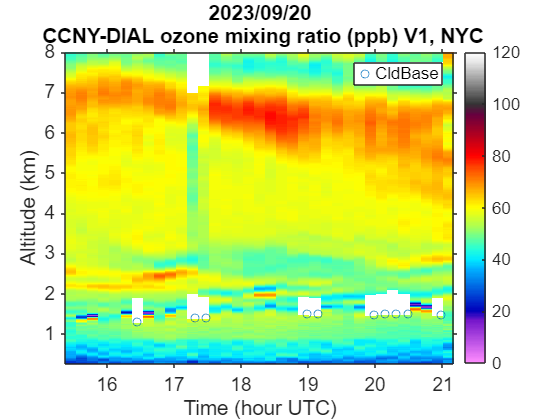

Show = true;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL ozone mixing ratio (ppb) V1, NYC'];
    NDplot2(O3ppb_sm,TimeInHour_avg,hkm_nr,title_str,[0.25,8],[0,120],14);
    hold on;
    plot(TimeInHour_avg,cldBaseZ(1,:),'o'); legend('CldBase')

    if save_figs == true
        % savefig(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyymmdd'),'v1']) ;
        % saveas(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyymmdd'),'v1.jpg']);
    end
end

## Calculate the aerosol correction term

Sm = 8*pi/3;
Sa = 50;   % 60 for smoke; 50 for urban aerosols
Rc = 1.005;  % reference value for the total-backscatter to molecular backscatter ratio
zsurf = 0.3;
zref = 8.0;   % 6.5, 7.5, 8.0 8.5

prof_299 = movmean(new_sigprof.merge299merge,3,1);
sigmaOff = 45.51*10^(-20);% O3 cross section at 299.1 (cm^2/molecule)
ae = 1.5;

N_O3 = movmean(N_O3_merge,21,1);
% N_O3 = N_O3_cld;
[N_O3_corr, abs299, aext299, N_absc_299, D_aext_299, rel_NO3] = o3_aerosol_iterative_solver(prof_299,hkm_nr,N_O3,Sm,Sa,Rc,zsurf,zref,am299,sigmaOff,ae,dsigma_hkm,frame_len_nr,dzm);   
img_id = (imag(abs299)~=0);
abs299(img_id)=nan;
abs299(:,cldBaseZ(1,:)<6)=nan; % if there is cloud lower than 6km, remove the aerosol retrieval
abs299(hkm_nr<0.6,:)=nan;aext299(hkm_nr<0.6,:)=nan;
N_absc_299(hkm_nr<0.6,:)=nan;D_aext_299(hkm_nr<0.6,:)=nan;
N_absc_299(:,cldBaseZ(1,:)<6)=nan;D_aext_299(:,cldBaseZ(1,:)<6)=nan;
N_O3_corr = N_O3_merge - fillmissing(N_absc_299,'constant',0)- fillmissing(D_aext_299,'constant',0);

%%% Wu add it on Aug.28, 2024
% when hkm_nr<zmin_aer, using a constant D_aext_299 and N_absc_299
zmin_aer=0.7; 
k1=find( abs(hkm_nr-zmin_aer)<=0.1);
ave_Nabsc299 = nanmean(N_absc_299(k1,:),1);
ave_Daext299 = nanmean(D_aext_299(k1,:),1);

ave_Nabsc299=fillmissing(ave_Nabsc299,'constant',0);
ave_Daext299=fillmissing(ave_Daext299,'constant',0);
k2=find( hkm_nr<=zmin_aer);
N_O3_corr2=N_O3_corr; 
N_O3_corr2(k2,:)=N_O3_corr2(k2,:)-ave_Nabsc299-ave_Daext299;

#### Aerosol Backscatter Coefficient Plot

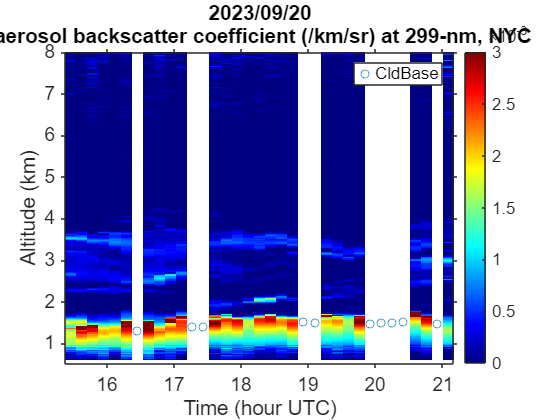

Show = true;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' aerosol backscatter coefficient (/km/sr) at 299-nm, NYC'];
    NDplot(abs299,TimeInHour_avg,hkm_nr,title_str,[0.5,zref],[0,3e-3],14);
    %NDplot(abs299,TimeInHour_avg,hkm_nr,title_str,[0.5,zref],[0,8e-3],14);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');

    if save_figs == true
        % savefig(gcf,[save_path,'abs299_',datestr(DateTime_avg(1),'yyyymmdd')]);
        % saveas(gcf,[save_path,'abs299_',datestr(DateTime_avg(1),'yyyymmdd'),'.jpg']);
    end
end

#### Aerosol Correction Plot

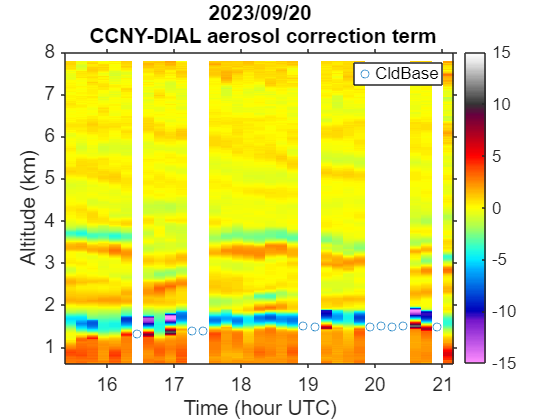

Show = true;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL aerosol correction term'];
    NDplot2(N_absc_299./NDAir_m3*1e9,TimeInHour_avg,hkm_nr,title_str,[0.6,zref],[-15,15],14);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');
end

Systematic error due to S ratio and AE

ae1 = 1;
% Sa2 = 50;
[N_O3_corr1,abs299_1,~,N_absc_299_1,D_aext_299_1,rel_NO3_1] = o3_aerosol_iterative_solver(prof_299,hkm_nr,N_O3_sm,Sm,Sa,Rc,zsurf,zref,am299,sigmaOff,ae1,dsigma_hkm,frame_len_nr,dzm);   
% [N_O3_corr2,abs299_2,aext299,N_absc_299_2,D_aext_299_2,rel_NO3_2] = o3_aerosol_iterative_solver(prof_299,hkm_nr,N_O3_sm,Sm,Sa2,Rc,zsurf,zref,am299,sigmaOff,ae,dsigma_hkm,frame_len_nr,dzm);   
% 
% title_str = [datestr(DateTime_avg(1),'yyyy/mm/dd'),' CCNY-DIAL aerosol corr term (AE:  2-1.5)'];
% NDplot((N_absc_299_1-N_absc_299)./NDAir_m3*1e9,TimeInHour_avg,hkm_nr,title_str,[0.3,7],[0,20],14);

eps_sys_aero = (N_absc_299_1-N_absc_299)./N_O3_corr;

Interference gas correction

sigma_so2_off = 4.073526E-19; % unit: cm2/molec
sigma_so2_on = 9.360870E-19;
dsigma_so2 = (sigma_so2_on-sigma_so2_off)*(10^-2)^2; %m2/molec

sigma_no2_off = 1.286967E-19; % unit: cm2/molec
sigma_no2_on = 7.455643E-20;
dsigma_no2 = (sigma_no2_on-sigma_no2_off)*(10^-2)^2; %m2/molec

## Calculate the statistical uncertainty

s_nr = 1./(snr_299_nr.^2) + 1./(snr_287_nr.^2) ;
s_fr = 1./(snr_299_fr.^2) + 1./(snr_287_fr.^2) ;
eps_nr=nan(size(s_nr));eps_fr=nan(size(s_fr));

for k = 1:len_t
    eps_nr(:,k)=sqrt(s_nr(:,k))./(2*dsigma_hkm.*N_O3_merge(:,k).*(vres_eff_nr*1e3));
    eps_fr(:,k)=sqrt(s_fr(:,k))./(2*dsigma_hkm_fr.*N_O3_merge(diff_nr_fr:end,k).*(vres_eff_fr*1e3));
end

k1 = find(hkm_nr>=start_merge_hkm,1,'first');
k2 = find(hkm_fr>=start_merge_hkm,1,'first');
eps_sta_mrg = eps_nr;
eps_sta_mrg(k1:end,:) = eps_fr(k2:end,:);
eps_sta_mrg(imag(eps_sta_mrg)~=0) = 1;

Estimate the systematic uncertainty and combined uncertainty 

eps_sys_NO2 = 0.005 ;
eps_sys_SO2 = 0.01 ;
eps_sys_Rayleigh = 0.01;
eps_sys_dsigma = 0.03;

eps_sys = sqrt(eps_sys_NO2.^2+eps_sys_SO2.^2+eps_sys_Rayleigh.^2+eps_sys_dsigma.^2+eps_sys_aero.^2);
eps_combined = sqrt(eps_sta_mrg.^2+fillmissing(eps_sys,'constant',0).^2);

Smoothing and screening

movnum1 = 51; % 200m 0-2km 1:533
N_O3_cld=N_O3_corr;
N_O3_cld(cld_mask)=nan;
N_O3_corr_scr=movmean(N_O3_cld,movnum1,1);

uncrmask = eps_sta_mrg>0.5|isnan(eps_sta_mrg)|eps_sta_mrg<0;
N_O3_corr_scr(uncrmask)=nan;

O3ppb_corr = N_O3_corr./NDAir_m3*1e9;
O3ppb_corr_scr=N_O3_corr_scr./NDAir_m3*1e9;

zmin_o3 = 0.25;
zmax_o3 = 7.0;

#### O3 (no aerosol Correction) Plot

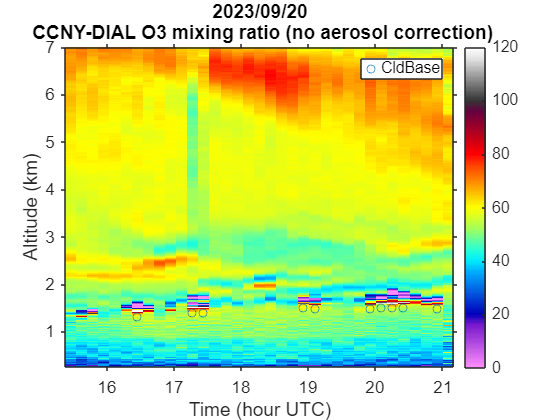

Show = true;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL O3 mixing ratio (no aerosol correction)'];
    NDplot2(O3ppb_mrg,TimeInHour_avg,hkm_nr,title_str,[zmin_o3,zmax_o3],[0,120],13);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');

    if save_figs == true
        % savefig(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyyMMdd'),'_no_aer_corr']);
        % saveas(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyyMMdd'),'_no_aer_corr.jpg']);
    end
end

#### O3 V1.5 Plot

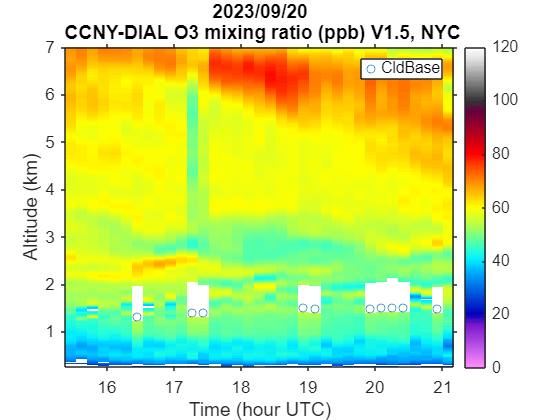

Show = true;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL O3 mixing ratio (ppb) V1.5, NYC'];
    NDplot2(O3ppb_corr_scr,TimeInHour_avg,hkm_nr,title_str,[zmin_o3,zmax_o3],[0,120],13);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');

    if save_figs == true
        % savefig(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyyMMdd'),'_aer_corr']);
        % saveas(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyyMMdd'),'_aer_corr.jpg']);
    end
end

h1_hkm = find(hkm_nr > 0.4,1,'first');
h2_hkm = find(hkm_nr > 6,1,'first');
movnum1=21;
movnum2=61;
movnum3=83;
N_O3_corr_sm = sglp_smooth(N_O3_corr,1,h1_hkm,h2_hkm,movnum1,movnum2,movnum3);
N_O3_corr_sm(cld_mask)=nan;
o3ppb_corr_sm=N_O3_corr_sm./NDAir_m3*1e9;

#### O3 V1.5 [smt] Plot

Show = false;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL O3 mixing ratio (ppb) V1.5 (smt), NYC'];
    NDplot2(o3ppb_corr_sm,TimeInHour_avg,hkm_nr,title_str,[zmin_o3,zmax_o3],[0,120],14);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');

    if save_figs == true
        % savefig(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyy/MM/dd'),'_aer_corr_sm']);
        % saveas(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyy/MM/dd'),'_aer_corr_sm.jpg']);
    end
end

#### O3 V2 Plot

Show = false;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL O3 mixing ratio (ppb) V2, NYC'];
    NDplot2(O3ppb_corr_scr,TimeInHour_avg,hkm_nr,title_str,[zmin_o3,zmax_o3],[0,120],13);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');

    if save_figs == true
        % savefig(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyy/MM/dd'),'_aer_scr']);
        % saveas(gcf,[save_path,'o3ppb',datestr(DateTime_avg(1),'yyyy/MM/dd'),'_aer_scr.jpg']);
    end
end

#### Statistical Uncertainty Plot

Show = false;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL Statistical Uncertainty'];
    NDplot(100*eps_sta_mrg,TimeInHour_avg,hkm_nr,title_str,[zmin_o3,zmax_o3],[0,50],13);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');

    if save_figs == true
        % savefig(gcf,[save_path,'statuncer', datestr(DateTime_avg(1),'yyyy/MM/dd')]);
        % saveas(gcf,[save_path,'statuncer', datestr(DateTime_avg(1),'yyyy/MM/dd'),'.jpg']);
    end
end

%% Wu add on Aug.28, 2024
% when hkm_nr<zmin_aer, using a constant (D_aext_299 and N_absc_299) to correct the ozone retrievals from near-ch
zmin_aer = 0.6; 
k1=find( abs(hkm_nr-zmin_aer) <= 0.05);
ave_Nabsc299 = nanmean(N_absc_299(k1,:),1);
ave_Daext299 = nanmean(D_aext_299(k1,:),1);
ave_Nabsc299 = fillmissing(ave_Nabsc299,'constant',0);
ave_Daext299 = fillmissing(ave_Daext299,'constant',0);
k2 = find(hkm_nr<=zmin_aer);

N_O3_corr2 = N_O3_corr_scr; %N_O3_corr
N_O3_corr2(k2,:) = N_O3_corr2(k2,:)-ave_Nabsc299-ave_Daext299;
N_O3_corr2(cld_mask) = nan;
N_O3_corr2_sm = sglp_smooth(N_O3_corr2,1,h1_hkm,h2_hkm,movnum1,movnum2,movnum3);
N_O3_corr2_sm(cld_mask) = nan;
o3ppb_corr2_sm = N_O3_corr2_sm./NDAir_m3*1e9;
o3ppb_corr2_sm(cld_mask) = nan;

#### O3 V3 Plot

Show = false;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL O3 mixing ratio (ppb) V3, NYC'];
    NDplot2(o3ppb_corr2_sm,TimeInHour_avg,hkm_nr,title_str,[zmin_o3,zmax_o3],[0,120],13); hold on; 
    plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');
end

## Compare with ground data 

% gdo3filename ='G:\CCNYShed_data\2B_Tech_O3\20240823_0828_1minave_O3_CCNYShed_V2.csv';
% % read data into a table
% T = readtable(gdo3filename,'Format','%f %f %f %f %f %{dd/MM/yy}D %{HH:mm:ss}D','Delimiter',',','HeaderLines',0,'ReadVariableNames',true );
% ground_O3_ppb=T{:,2};% 1nd col ozone ppbv
% %last two cols are the datetime (local time)
% Tdates=datetime(T{:,end-1},'Format','dd/MM/yyyy HH:mm:SS');
% ground_O3_ppb_datetime=Tdates + timeofday(T{:,end});

% % Weather data
% weatherfilename ='/Users/Tinker/Documents/MATLAB/Ceilometer/WeatherStation/nycairptemp_2023sep5_7_5min.csv';
% T2= readtable(weatherfilename,'Format','%s %{dd/MM/yy HH:mm}D %f %f %f %f %f %f %f ','Delimiter',',','HeaderLines',0,'ReadVariableNames',true );
% temp=T2{:,3};% 1nd col ozone ppbv
% t_temp=datetime(T2{:,2},'Format','dd/MM/yyyy HH:mm:SS');

% % O3-DIAL data
% tdiff =hours(4);
% idh = find(hkm_nr>=0.25,1,'first');
% ind_gd_ozone=isbetween(ground_O3_ppb_datetime+tdiff,DateTime_avg(1)-minutes(10),DateTime_avg(end)+minutes(10));
% % ind_gd_ozone=isbetween(ground_O3_ppb_datetime+tdiff,datetime(2023,9,5,0,0,0),datetime(2023,9,8,0,0,0));
% 
% f1=figure;
% % plot(ground_O3_ppb_datetime(ind_gd_ozone)+tdiff,ground_O3_ppb(ind_gd_ozone),'r-');
% hold on;
% plot(DateTime_avg,O3ppb_corr_scr(idh,:),'bo-');
% set(gca,'LineWidth',1,'FontSize',13);
% legend('in-situ','Lidar@220m');
% xlabel('UTC Time (Hour)');
% ylabel('Ozone Mixing Ratio (ppbv)');
% ylim([20,100]);
% title(datestr(DateTime_avg(1),'yyyy.mm.dd'))
% grid on;
% set(gca,'FontSize',14); 
% savefig(f1,[save_path,'o3ppb',datestr(DateTime(1,1),'yyyymmdd'),'gdcomp'],'compact');
% saveas(f1,[save_path,'o3ppb',datestr(DateTime(1,1),'yyyymmdd'),'gdcomp.jpg']);

## Output the results

hkm_max = 10; % maximum range to report [km]
zm = 1e3*hkm_nr(hkm_nr<=hkm_max); % altitude [m] 

o3_nd = N_O3_corr_scr(hkm_nr<=hkm_max,:);% o3 number density [molec/m^3] 
% Wu added for some negative result values on July 12, 2024
kc1 = find(o3_nd<0);
o3_nd(kc1) = NaN;

o3_nd_comb_uncer = eps_combined(hkm_nr<=hkm_max,:).*o3_nd;% o3 number density combined uncertainty [molec/m^3]
o3_nd_rand_uncer = eps_sta_mrg(hkm_nr<=hkm_max,:).*o3_nd;% o3 number density random (statistical) uncertainty [molec/m^3]
o3_nd_sys_uncer = eps_sys(hkm_nr<=hkm_max,:).*o3_nd;% o3 number density systematic uncertainty [molec/m^3]

vres_eff_mrg_mat = repmat(vres_eff_mrg(hkm_nr<=hkm_max),1,length(TimeInHour_avg));
o3_nd_vrt_res = 1e3*vres_eff_mrg_mat;% o3 number density vertical resolution [m]

o3ppb_scr = O3ppb_corr_scr;% o3 mixing ratio [ppbv]
o3_mr = 1e-3*o3ppb_scr(hkm_nr<=hkm_max,:);% o3 mixing ratio [ppmv]


o3_mr_comb_uncer = eps_combined(hkm_nr<=hkm_max,:).*o3_mr;%o3 mixing ratio combined uncertainty [ppmv]
o3_mr_rand_uncer = eps_sta_mrg(hkm_nr<=hkm_max,:).*o3_mr;% o3 mixing ratio random (statistical) uncertainty [ppmv]
o3_mr_sys_uncer = eps_sys(hkm_nr<=hkm_max,:).*o3_mr; % o3 mixing ratio systematic uncertainty [ppmv]
pressure = 1e-2*P_prof(hkm_nr<=hkm_max); % Pressure profile [hpa]
temperature = T_prof(hkm_nr<=hkm_max); % Temperature profile [k]

o3result.nAvg = nAvg; % number of profiles to average [profile]
o3result.DateTime = DateTime; % date time array of the original time resolution in UTC [yyyy-MMM-dd HH:mm:ss]
o3result.DateTime_avg = DateTime_avg; % averaged date time array in UTC [yyyy-MMM-dd HH:mm:ss]
o3result.TimeInHour = TimeInHour; % time in hour of the original time resolution in UTC [hour]
o3result.TimeInHour_avg = TimeInHour_avg;% averaged time in hour  in UTC [hour]
o3result.alt = zm;% altitude [m] 
o3result.o3_nd = o3_nd;
o3result.o3_nd_comb_uncer = o3_nd_comb_uncer;% o3 number density [molec/m^3] combined uncertainty
o3result.o3_nd_rand_uncer = o3_nd_rand_uncer ;% o3 number density random (statistical) uncertainty
o3result.o3_nd_sys_uncer = o3_nd_sys_uncer;% o3 number density systematic uncertainty
o3result.o3_nd_vrt_res = o3_nd_vrt_res;% o3 number density vertical resolution [m]
o3result.o3_mr = o3_mr; % o3 mixing ratio [ppmv] 
o3result.o3_mr_comb_uncer = o3_mr_comb_uncer;%o3 mixing ratio combined uncertainty [ppmv]
o3result.o3_mr_rand_uncer = o3_mr_rand_uncer;%o3 mixing ratio random (statistical) uncertainty [ppmv]
o3result.o3_mr_sys_uncer = o3_mr_sys_uncer; % o3 mixing ratio systematic uncertainty [ppmv]
o3result.p = pressure; % pressure profile [hpa]
o3result.t = temperature; % temperature profile [K]
o3result.p_source ='radiosonde';
o3result.t_source = 'radiosonde';
o3result.absc299 = abs299(hkm_nr<=hkm_max,:); % aerosol backscatter at 299nm
o3result.aext299 = aext299(hkm_nr<=hkm_max,:); % aerosol extinction at 299nm
o3result.N_absc_299 = N_absc_299(hkm_nr<=hkm_max,:); % aerosol backscatter differential correction to the o3 number density
o3result.D_aext_299 = D_aext_299(hkm_nr<=hkm_max,:);% aerosol extinction differential correction to the O3 number density
o3result.Sratio = Sa;% S ratio used to retrieve aerosol backscatter
o3result.Rc = Rc;  % reference value for the total-backscatter to molecular backscatter ratio
o3result.zref = zref;% the altitude start to retrieve aerosol
o3result.sigma299 = sigmaOff; % the O3 cross-section of 299nm
o3result.ae = ae;% angstrom exponent used to retrieve aerosol backscatter

o3fileName = strjoin([save_path,'o3result', datestr(DateTime(1),'yyMMdd'),'.mat'], '');
save(o3fileName,'o3result');

test_create_hdf(save_path, o3result);